## Create an Empty Robot Model

robot = rigidBodyTree('DataFormat','column','MaxNumBodies',3);

fprintf('=== Empty robot created ===\n');

=== Empty robot created ===


fprintf('Number of bodies so far: %d\n', robot.NumBodies);

Number of bodies so far: 0


fprintf('The robot currently has only a fixed base frame.\n\n');

The robot currently has only a fixed base frame.



showdetails(robot)

--------------------
Robot: (0 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
--------------------


## Define Link Lengths

% These are the physical dimensions of the arm. Both links are 0.3 m.

L1 = 0.3;   % Length of link 1 (metres)
L2 = 0.3;   % Length of link 2 (metres)

fprintf('=== Link lengths defined ===\n');

=== Link lengths defined ===


fprintf('  L1 = %.2f m\n', L1);

  L1 = 0.30 m


fprintf('  L2 = %.2f m\n', L2);

  L2 = 0.30 m


fprintf('  Total reach (L1+L2) = %.2f m\n', L1+L2);

  Total reach (L1+L2) = 0.60 m


fprintf('  Inner dead zone |L1-L2| = %.2f m\n', abs(L1-L2));

  Inner dead zone |L1-L2| = 0.00 m


## Add Link 1 (Upper Arm)

% The first link connects to the base via a revolute (rotational) joint.
% The joint sits at the origin and rotates about the z-axis.

body1  = rigidBody('link1');
joint1 = rigidBodyJoint('joint1','revolute');
setFixedTransform(joint1, trvec2tform([0 0 0]));
joint1.JointAxis = [0 0 1];
body1.Joint = joint1;
addBody(robot, body1, 'base');

fprintf('=== Link 1 added ===\n');

=== Link 1 added ===


fprintf('Number of bodies: %d\n', robot.NumBodies);

Number of bodies: 1


fprintf('Joint type: %s\n', joint1.Type);

Joint type: revolute


fprintf('Joint axis: [%d %d %d] (rotation about z)\n', joint1.JointAxis);

Joint axis: [0 0 1] (rotation about z)


fprintf('Parent body: base\n\n');

Parent body: base



showdetails(robot)

--------------------
Robot: (1 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   
--------------------


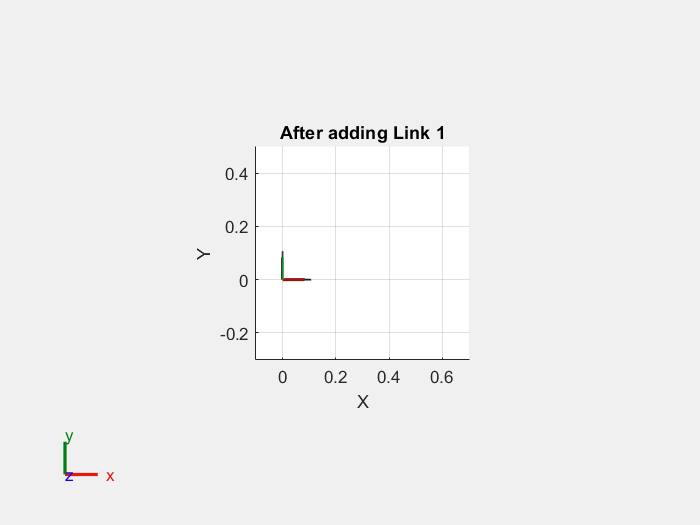


% Visualise the robot so far (just 1 link)
figure('Name','Step 1: Link 1 Added')
show(robot, homeConfiguration(robot));
view(2)
ax = gca; ax.Projection = 'orthographic';
title('After adding Link 1')
axis([-0.1 0.7 -0.3 0.5])

## Add Link 2 (Forearm)

% The second link is attached to the end of link1. Its joint is placed
% at a distance of L1 along the x-axis from joint1.

body2  = rigidBody('link2');
joint2 = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint2, trvec2tform([L1 0 0]));
joint2.JointAxis = [0 0 1];
body2.Joint = joint2;
addBody(robot, body2, 'link1');

fprintf('=== Link 2 added ===\n');

=== Link 2 added ===


fprintf('Number of bodies: %d\n', robot.NumBodies);

Number of bodies: 2


fprintf('Joint type: %s\n', joint2.Type);

Joint type: revolute


fprintf('Offset from parent (link1): [%.2f, 0, 0] m\n', L1);

Offset from parent (link1): [0.30, 0, 0] m


fprintf('Parent body: link1\n\n');

Parent body: link1



showdetails(robot)

--------------------
Robot: (2 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   
--------------------


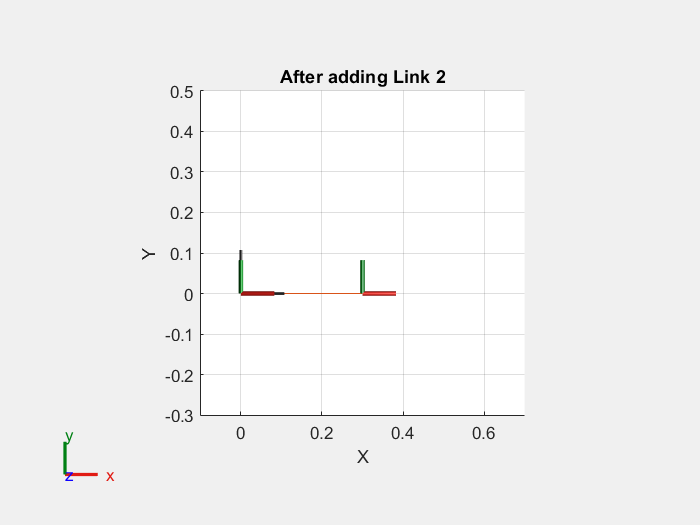


% Visualise with both links
figure('Name','Step 2: Link 2 Added')
show(robot, homeConfiguration(robot));
view(2)
ax = gca; ax.Projection = 'orthographic';
title('After adding Link 2')
axis([-0.1 0.7 -0.3 0.5])

## Add the End Effector (Tool)

% The tool is a reference frame fixed rigidly to the tip of link2.
% It uses a *fixed* joint — it does not add a degree of freedom.

toolBody = rigidBody('tool');
fixJoint = rigidBodyJoint('fix1','fixed');
setFixedTransform(fixJoint, trvec2tform([L2 0 0]));
toolBody.Joint = fixJoint;
addBody(robot, toolBody, 'link2');

fprintf('=== End effector (tool) added ===\n');

=== End effector (tool) added ===


fprintf('Number of bodies: %d\n', robot.NumBodies);

Number of bodies: 3


fprintf('Joint type: %s  (no extra DOF)\n', fixJoint.Type);

Joint type: fixed  (no extra DOF)


fprintf('Offset from parent (link2): [%.2f, 0, 0] m\n\n', L2);

Offset from parent (link2): [0.30, 0, 0] m



showdetails(robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   tool(3)  
   3         tool          fix1         fixed            link2(2)   
--------------------


## Robot Home Configuration

%Complete Robot Visualisation

q_home = homeConfiguration(robot);
fprintf('=== Complete robot ===\n');

=== Complete robot ===


fprintf('Home configuration (all joints at 0 rad):\n');

Home configuration (all joints at 0 rad):


for j = 1:length(q_home)
    fprintf('  Joint %d: %.4f rad  (%.1f deg)\n', j, q_home(j), rad2deg(q_home(j)));
end

  Joint 1: 0.0000 rad  (0.0 deg)
  Joint 2: 0.0000 rad  (0.0 deg)


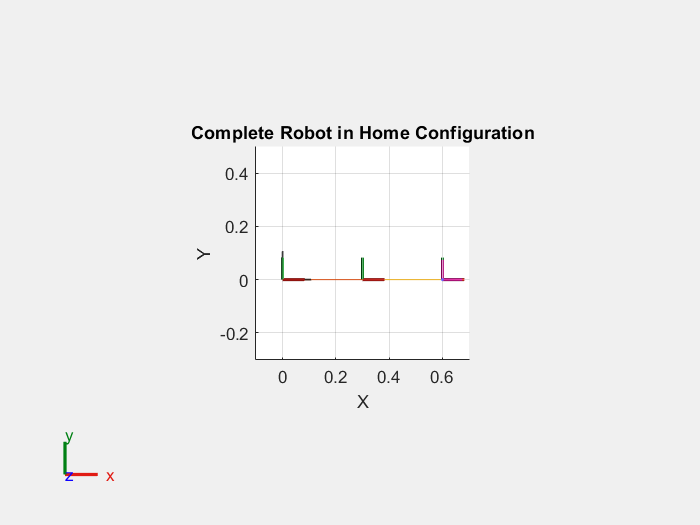


% Show the complete robot
figure('Name','Complete Robot — Home Configuration')
show(robot, q_home);
view(2)
ax = gca; ax.Projection = 'orthographic';
title('Complete Robot in Home Configuration')
axis([-0.1 0.7 -0.3 0.5])

## non-zero configuration

% Also show a non-zero configuration so students see it move
q_test = [pi/4; -pi/3];
fprintf('\nTest configuration:\n');


Test configuration:


for j = 1:length(q_test)
    fprintf('  Joint %d: %.4f rad  (%.1f deg)\n', j, q_test(j), rad2deg(q_test(j)));
end

  Joint 1: 0.7854 rad  (45.0 deg)
  Joint 2: -1.0472 rad  (-60.0 deg)


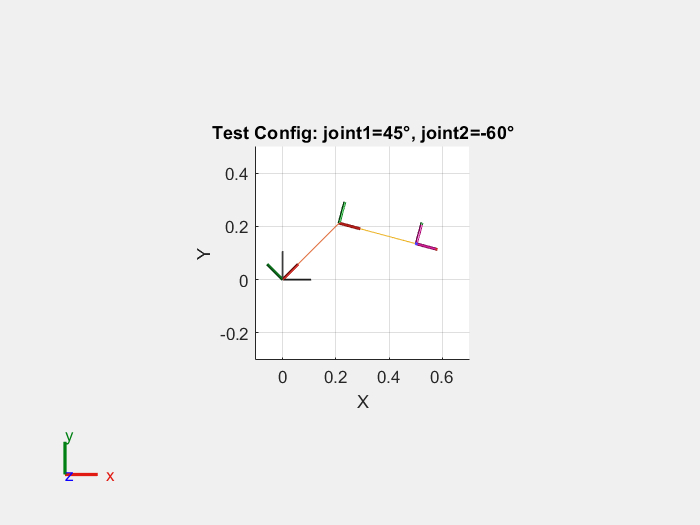


figure('Name','Complete Robot — Test Configuration')
show(robot, q_test);
view(2)
ax = gca; ax.Projection = 'orthographic';
title(sprintf('Test Config: joint1=%.0f°, joint2=%.0f°', rad2deg(q_test(1)), rad2deg(q_test(2))))
axis([-0.1 0.7 -0.3 0.5])

## end-effector position via FK

T_ee = getTransform(robot, q_test, 'tool');
ee_pos = T_ee(1:3,4)';
fprintf('End-effector position (FK): x=%.3f, y=%.3f, z=%.3f m\n', ee_pos);

End-effector position (FK): x=0.502, y=0.134, z=0.000 m


## Visualise the Workspace

% Before commanding the robot, it is useful to understand _where_ the end
% effector can reach. For a 2-link planar arm the reachable workspace is
% an annular ring (a donut shape).

outerR = L1 + L2;
innerR = abs(L1 - L2);

fprintf('=== Workspace Analysis ===\n');

=== Workspace Analysis ===


fprintf('Outer radius (max reach): %.2f m\n', outerR);

Outer radius (max reach): 0.60 m


fprintf('Inner radius (dead zone): %.2f m\n', innerR);

Inner radius (dead zone): 0.00 m


if innerR == 0
    fprintf('Note: L1 == L2, so the robot can reach the base origin.\n');
end

Note: L1 == L2, so the robot can reach the base origin.


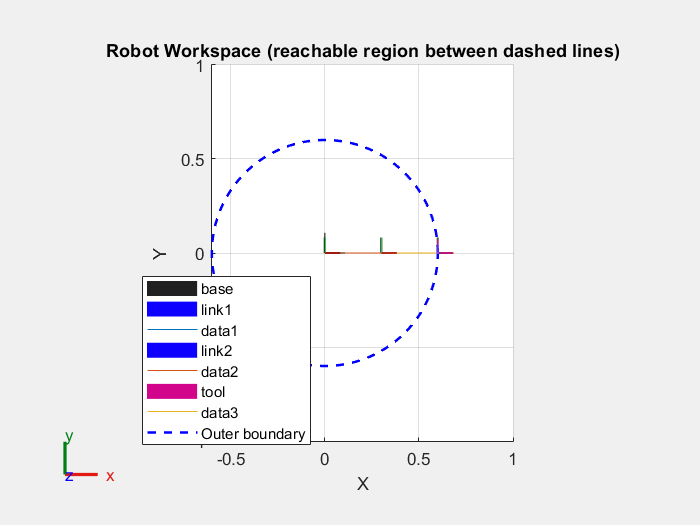


figure('Name','Workspace Visualisation')
show(robot, homeConfiguration(robot));
view(2)
ax = gca; ax.Projection = 'orthographic';
hold on

th = linspace(0, 2*pi, 200);
plot(outerR*cos(th), outerR*sin(th), 'b--', 'LineWidth', 1.5, 'DisplayName','Outer boundary')
if innerR > 0
    plot(innerR*cos(th), innerR*sin(th), 'r--', 'LineWidth', 1.5, 'DisplayName','Inner boundary')
end
legend('Location','best')
title('Robot Workspace (reachable region between dashed lines)')
axis equal
hold off

##  Define the Trajectory Parameters

% We want the end effector to trace a circle in the xy-plane over 10
% seconds. Let's first define and inspect the parameters.

t      = (0:0.2:10)';          % Time vector (0.2 s steps)
count  = length(t);
center = [0.3, 0.1, 0];       % Centre of the circle (x, y, z)
radius = 0.15;                 % Circle radius (metres)

fprintf('=== Trajectory Parameters ===\n');

=== Trajectory Parameters ===


fprintf('Duration:    %.1f s\n', t(end));

Duration:    10.0 s


fprintf('Time step:   %.1f s\n', t(2)-t(1));

Time step:   0.2 s


fprintf('Waypoints:   %d\n', count);

Waypoints:   51


fprintf('Circle centre: [%.2f, %.2f, %.2f] m\n', center);

Circle centre: [0.30, 0.10, 0.00] m


fprintf('Circle radius: %.2f m\n', radius);

Circle radius: 0.15 m


## Generate the Waypoints

% Compute the Cartesian (x,y,z) coordinates for each waypoint around the
% circle.

theta  = t * (2*pi / t(end));
points = center + radius * [cos(theta), sin(theta), zeros(size(theta))];

fprintf('=== First 5 waypoints ===\n');

=== First 5 waypoints ===


fprintf('  %4s   %8s   %8s   %8s\n', 'i', 'x (m)', 'y (m)', 'z (m)');

     i      x (m)      y (m)      z (m)


fprintf('  %4s   %8s   %8s   %8s\n', '----', '--------', '--------', '--------');

  ----   --------   --------   --------


for i = 1:5
    fprintf('  %4d   %8.4f   %8.4f   %8.4f\n', i, points(i,1), points(i,2), points(i,3));
end

     1     0.4500     0.1000     0.0000
     2     0.4488     0.1188     0.0000
     3     0.4453     0.1373     0.0000
     4     0.4395     0.1552     0.0000
     5     0.4314     0.1723     0.0000


fprintf('  ...    ...        ...        ...\n');

  ...    ...        ...        ...


fprintf('  %4d   %8.4f   %8.4f   %8.4f\n', count, points(end,1), points(end,2), points(end,3));

    51     0.4500     0.1000     0.0000


## Reachability Check

% Before running IK, verify that every waypoint is inside the workspace.

distances = vecnorm(points(:,1:2), 2, 2);

fprintf('\n=== Reachability Check ===\n');


=== Reachability Check ===


fprintf('Min distance from base: %.4f m  (inner boundary: %.2f m) — ', min(distances), innerR);

Min distance from base: 0.1667 m  (inner boundary: 0.00 m) — 

if min(distances) >= innerR
    fprintf('OK\n');
else
    fprintf('WARNING: some points inside dead zone!\n');
end

OK


fprintf('Max distance from base: %.4f m  (outer boundary: %.2f m) — ', max(distances), outerR);

Max distance from base: 0.4661 m  (outer boundary: 0.60 m) — 

if max(distances) <= outerR
    fprintf('OK\n');
else
    fprintf('WARNING: some points outside reach!\n');
end

OK


## Trajectory overlaid on the workspace

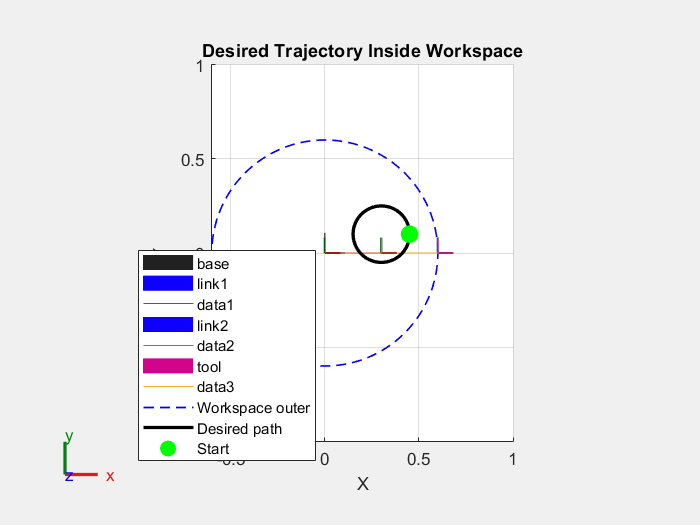

figure('Name','Trajectory vs Workspace')
show(robot, homeConfiguration(robot));
view(2)
ax = gca; ax.Projection = 'orthographic';
hold on
plot(outerR*cos(th), outerR*sin(th), 'b--', 'LineWidth', 1, 'DisplayName','Workspace outer')
if innerR > 0
    plot(innerR*cos(th), innerR*sin(th), 'r--', 'LineWidth', 1, 'DisplayName','Workspace inner')
end
plot(points(:,1), points(:,2), 'k-', 'LineWidth', 2, 'DisplayName','Desired path')
plot(points(1,1), points(1,2), 'go', 'MarkerSize', 10, 'MarkerFaceColor','g', 'DisplayName','Start')
legend('Location','best')
title('Desired Trajectory Inside Workspace')
axis equal
hold off

## Set Up the Inverse Kinematics Solver

% The |inverseKinematics| object wraps a numerical optimisation.
%
% *Key concept — the weight vector:*  The solver targets a full 6-DOF
% pose (3 orientation + 3 position), but our planar task only cares about
% x and y position. The |weights| vector tells the solver which
% components matter:
%
%   weights = [wx  wy  wz  px  py  pz]
%            orientation     position

ik          = inverseKinematics('RigidBodyTree', robot);
weights     = [0, 0, 0, 1, 1, 0];
endEffector = 'tool';

fprintf('=== IK Solver Created ===\n');

=== IK Solver Created ===


fprintf('End effector frame: "%s"\n', endEffector);

End effector frame: "tool"


fprintf('Weight vector: [%.0f %.0f %.0f | %.0f %.0f %.0f]\n', weights);

Weight vector: [0 0 0 | 1 1 0]


fprintf('  Orientation weights (wx,wy,wz): ignored (all 0)\n');

  Orientation weights (wx,wy,wz): ignored (all 0)


fprintf('  Position weights (px,py,pz): x=%.0f, y=%.0f, z=%.0f\n', weights(4), weights(5), weights(6));

  Position weights (px,py,pz): x=1, y=1, z=0



q0   = homeConfiguration(robot);
ndof = length(q0);
qs   = zeros(count, ndof);

fprintf('Degrees of freedom: %d\n', ndof);

Degrees of freedom: 2


fprintf('Pre-allocated solution matrix: %d x %d\n', count, ndof);

Pre-allocated solution matrix: 51 x 2


## Solve a Single Waypoint (Demonstration)

% Before solving the full trajectory, let's solve just the first point
% and inspect the result to understand what the solver returns.

point1   = points(1,:);
desiredT = trvec2tform(point1);

fprintf('=== Single-Point IK Demo ===\n');

=== Single-Point IK Demo ===


fprintf('Target position: [%.4f, %.4f, %.4f] m\n', point1);

Target position: [0.4500, 0.1000, 0.0000] m


fprintf('\nDesired transform (4x4 homogeneous matrix):\n');


Desired transform (4x4 homogeneous matrix):


disp(desiredT)

    1.0000         0         0    0.4500
         0    1.0000         0    0.1000
         0         0    1.0000         0
         0         0         0    1.0000




qSol1 = ik(endEffector, desiredT, weights, q0);

fprintf('IK solution:\n');

IK solution:


for j = 1:ndof
    fprintf('  Joint %d: %.4f rad  (%.1f deg)\n', j, qSol1(j), rad2deg(qSol1(j)));
end

  Joint 1: -0.4760 rad  (-27.3 deg)
  Joint 2: 1.3892 rad  (79.6 deg)


## Verify with forward kinematics

T_check = getTransform(robot, qSol1, endEffector);
actual_pos = T_check(1:3,4)';
pos_error  = norm(point1 - actual_pos);
fprintf('\nVerification (FK of solution):\n');


Verification (FK of solution):


fprintf('  Actual position: [%.4f, %.4f, %.4f] m\n', actual_pos);

  Actual position: [0.4500, 0.1000, 0.0000] m


fprintf('  Position error:  %.6f m  (should be near zero)\n', pos_error);

  Position error:  0.000000 m  (should be near zero)


## Robot at the Desired Position

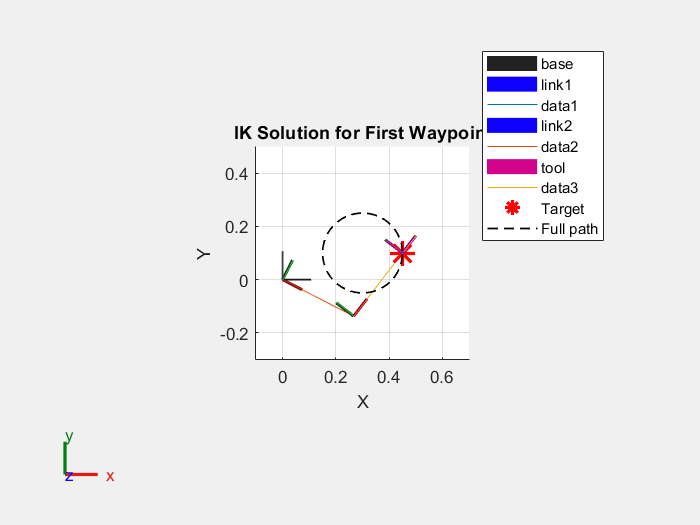


figure('Name','Single IK Solution')
show(robot, qSol1);
view(2)
ax = gca; ax.Projection = 'orthographic';
hold on
plot(point1(1), point1(2), 'r*', 'MarkerSize', 15, 'LineWidth', 2, 'DisplayName','Target')
plot(points(:,1), points(:,2), 'k--', 'LineWidth', 1, 'DisplayName','Full path')
legend('Location','best')
title('IK Solution for First Waypoint')
axis([-0.1 0.7 -0.3 0.5])
hold off

## Solve the Full Trajectory

% Now loop through all waypoints. Each solve is warm-started with the
% previous solution so the trajectory is smooth.

fprintf('=== Solving full trajectory (%d waypoints) ===\n', count);

=== Solving full trajectory (51 waypoints) ===



qInitial = q0;
for i = 1:count
    point = points(i,:);
    qSol  = ik(endEffector, trvec2tform(point), weights, qInitial);
    qs(i,:) = qSol;
    qInitial = qSol;

    % Print progress every 10 waypoints
    if mod(i,10) == 0 || i == 1 || i == count
        fprintf('  Waypoint %3d/%d — Joint1: %+7.2f deg, Joint2: %+7.2f deg\n', ...
            i, count, rad2deg(qSol(1)), rad2deg(qSol(2)));
    end
end

  Waypoint   1/51 — Joint1:  -27.27 deg, Joint2:  +79.60 deg
  Waypoint  10/51 — Joint1:  -10.80 deg, Joint2:  +87.46 deg
  Waypoint  20/51 — Joint1:  -15.62 deg, Joint2: +124.74 deg
  Waypoint  30/51 — Joint1:  -64.11 deg, Joint2: +146.92 deg
  Waypoint  40/51 — Joint1:  -64.67 deg, Joint2: +112.92 deg
  Waypoint  50/51 — Joint1:  -30.27 deg, Joint2:  +81.04 deg
  Waypoint  51/51 — Joint1:  -27.27 deg, Joint2:  +79.60 deg



fprintf('\nAll %d waypoints solved successfully.\n', count);


All 51 waypoints solved successfully.


## Animate the Robot

% Watch the arm trace the circle. The black curve is the desired
% trajectory; the robot should follow it closely.

fprintf('=== Starting animation at %d fps ===\n', 15);

=== Starting animation at 15 fps ===


fprintf('Watch the robot trace the circular path...\n');

Watch the robot trace the circular path...


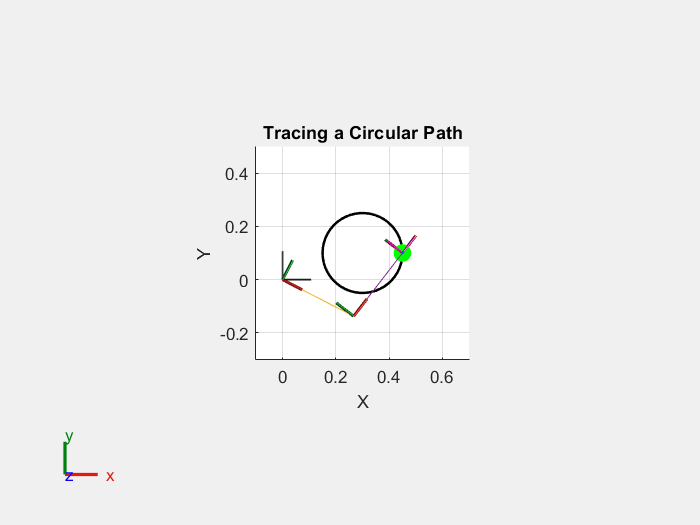


figure('Name','Robot Animation')
show(robot, qs(1,:)');
view(2)
ax = gca; ax.Projection = 'orthographic';
hold on
plot(points(:,1), points(:,2), 'k', 'LineWidth', 1.5)
plot(points(1,1), points(1,2), 'go', 'MarkerSize', 10, 'MarkerFaceColor','g')
axis([-0.1 0.7 -0.3 0.5])
title('Tracing a Circular Path')

framesPerSecond = 15;
r = rateControl(framesPerSecond);
for i = 1:count
    show(robot, qs(i,:)', 'PreservePlot', false);
    drawnow
    waitfor(r);
end

fprintf('Animation complete.\n');

Animation complete.
